Aby to fungovalo, musí se přidat cesta, zároveň zavedeme nápovědu (stačí spustit na začátku relace jednou)

addpath(genpath('C:\Fyzing\Baka\MATLAB\MNPBEM17'));
run('C:\Fyzing\Baka\MATLAB\MNPBEM17/makemnpbemhelp.m');

Removing existing index directory at C:\Fyzing\Baka\MATLAB\MNPBEM17\help\helpsearch-v4_en
Process Duration: 0.001595
Successfully created search database.


clc 
clear all
close all

Set up the dielectric environment and options for BEM:

%  options for BEM simulation
opret =  bemoptions( 'sim', 'ret', 'interp', 'curv' );
%  table of dielectric functions
epstab = { epsconst( 1),  epsdrude('myAg') };  %epstable( 'silver.dat' ) };

particles:

p1 = trirod( 30, 100, [ 20, 10, 20 ] );
p1 = rot(p1, 90, [0,1,0]);
p1 = shift( p1, [ 0, 30 ,50 ] );

p2 = trirod( 30, 100, [ 20, 10, 20 ] );
p2 = rot(p2, 90, [1,0,0]);
p2 = shift( p2, [ 30, 0, -50 ] );

n1 for the circumference of the rod, n2 for the polar angles of the rod caps, n3 for the cylinder-shaped middle part of the rod, and

p = comparticle( epstab, { p1, p2 }, [ 2, 1; 2, 1 ], 1, 2, opret );

## Plot the particles

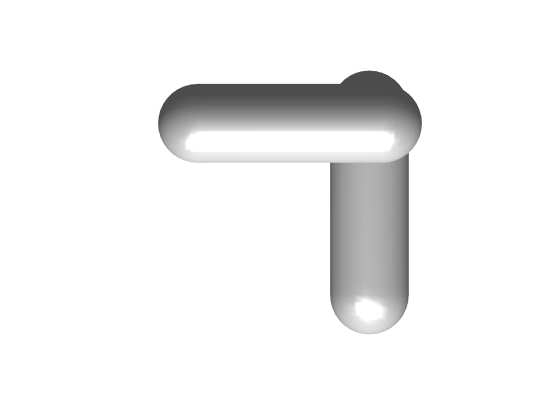

clf
plot( p, 'FaceColor', [1,1,1] );
xlim("auto")
ylim("auto")
zlim("auto")
view([0 90])

## EELS to find the right prefactor

%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.3, 0.446 * 2.99792458e8 );
%  impact parameters 
[X, Y] = meshgrid(linspace(-40,40,70),linspace(-40,40,70));
imp = [ X(:) , Y(:) ]; %linspace( -30, 30, 32 );
%  loss energies in eV
%ene = [ 2.764490219193807885e+00, 2.961953806279079782e+00 ];
ene = linspace(0.5,3,15);
% ene = [4.2,  4.5] * 1e15 * 1.05457182e-34 / 1.602e-19 ; %linspace( 2.5, 4.5, 60 );

%  convert energies to nm
units;  enei = eV2nm ./ ene;

## Retarded

%%  BEM solution
%  BEM solver
bem = bemsolver( p, opret );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opret );
%  surface and bulk losses
[ psurf, pbulk ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver (retarded)', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurf( :, ien ), pbulk( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver (retarded)', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

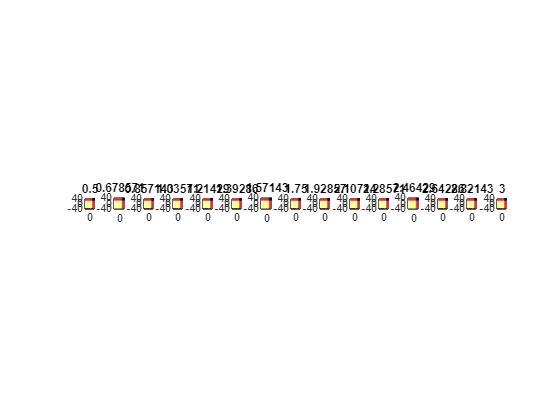

%%  final plot
%  electron energy loss probability
figure()
for i = 1:length( enei )
    subplot(1,length( enei ),i);
    pc = pcolor(X, Y, reshape(psurf(:,i) , size(X)) );
    pc.EdgeAlpha=0;
    colormap inferno;
    title(ene(i));
    axis square;

end

## Comparison of quasistatic and retarded calculation in spectra for a few points

For particles with following parameters 

We get different spectra using quasistatic /  retarded calculations

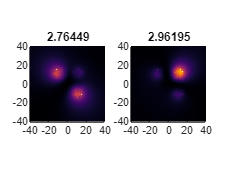 / 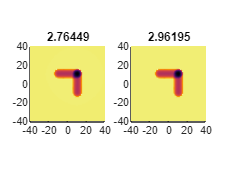

We will thus map the "full" spectra in a few points: 

%%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.3, 0.446 * 2.99792458e8 );
%%  impact parameters 
imp =  [[0,0],
        [16,16],
        [10,-16]];
%% loss energies in eV
% ene = [ 2.764490219193807885e+00, 2.961953806279079782e+00 ]
ene = linspace(2,3,50);
% ene = [4.2,  4.5] * 1e15 * 1.05457182e-34 / 1.602e-19 ; %linspace( 2.5, 4.5, 60 );

%  convert energies to nm
units;  enei = eV2nm ./ ene;



%% retarded BEM solution

Unrecognized function or variable 'opstat'.

%  BEM solver
bem = bemsolver( p, opret );
%  electron beam excitation
exc = electronbeam( p, imp, width, vel, opret );
%  surface and bulk losses
[ psurfret, pbulkret ] = deal( zeros( numel( imp(:,1) ), numel( enei ) ) );

multiWaitbar( 'BEM solver (ret)', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurfret( :, ien ), pbulkret( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver (ret)', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

Plotting the spectra:

clf
figure()
for iimp = 1:length(imp)
    subplot(1,length(imp),iimp)
    %plot(ene, psurfstat(iimp,:),"Color",[0 1 1])
    hold on
    plot(ene, psurfret(iimp,:),"Color",[1 0 0])
    title(imp(iimp,:))
end